# Approximating Fourier Transform

## Discrete Fourier Transform (DFT)

The Fourier transform is a mathematical operation which transforms a function over time into its frequency spectrum, representing how the function would be decomposed into periodic functions. This operation is defined by the integral


$$X(\xi) = \mathcal F(f(x)) = \int_{-\infty} ^{\infty} f(x) e^{-2\pi i\xi x} \; dx$$


Discretizing this integral, if we have some time series $x_1, x_2, \dots, x_n$, then the DFT is defined by


$$X_k = \sum_{n = 0} ^{N - 1} x_n e^{-2\pi i\frac{k}{N}n}$$


We can neatly represent this calculation using the DFT matrix, where each element is given by


$$W_{ij} = \frac{\omega^{i \cdot j}}{\sqrt N}$$


where the wiggle factor $\omega = e^{-2\pi i/N}$. To compute the inverse Fourier Transform, or in this case, the inverse DFT, we simply inverse the matrix. Since the matrix is unitary, we simply just take the conjugate transpose of the matrix. 

For information on implementation, see dft.m and idft.m.

Furthermore, for reference, I have used angular frequency for the axis. Hence, we have the following examples:

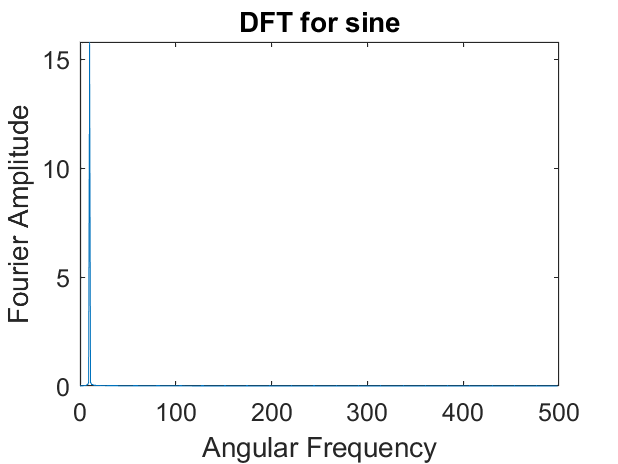

samples = 1000;
t = linspace(0, 2*pi, samples)';
x1 = sin(10*t);
X1 = dft(x1);
w = fourierFreqs(t);
figure('WindowStyle', 'docked');
plot(w(1:samples/2), (abs(X1(1:samples/2))))
xlabel("Angular Frequency")
ylabel("Fourier Amplitude")
title("DFT for sine")


% calculating the dominant frequency
maximum = max(X1(1:samples/2));
max_ind = find(X1(1:samples/2) == maximum);
disp("The dominant angular frequency for sin(10x) is")

The dominant angular frequency for sin(10x) is


disp(w(max_ind))

    9.9900



disp("which is near 10, the actual value.")

which is near 10, the actual value.


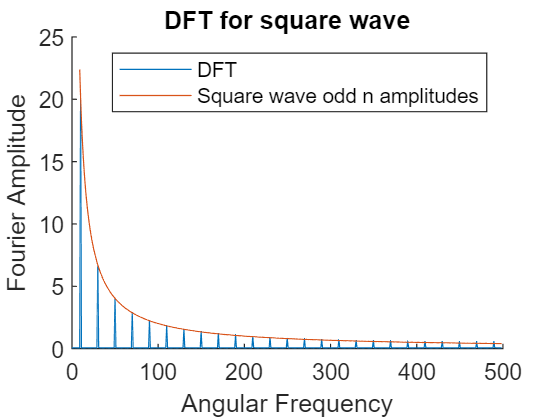


% square wave
x2 = square(10 * t);
X2 = dft(x2);
figure
hold on
plot(w(1:samples/2), (abs(X2(1:samples/2))))
plot(w(samples/100:samples/2), 20.1331./(0.1 * w(samples/100:samples/2)))
xlabel("Angular Frequency")
ylabel("Fourier Amplitude")
title("DFT for square wave")
legend("DFT", "Square wave odd n amplitudes")
hold off

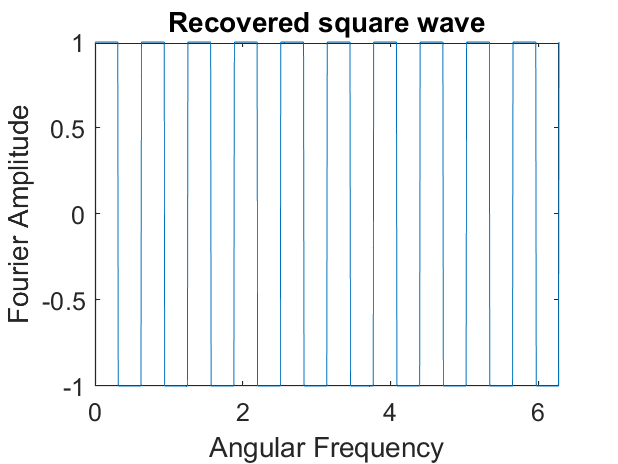


% recovering square wave from FT using inverse DFT
x2i = idft(X2);
figure
plot(t(1:samples), real(x2i(1:samples)))
xlabel("Angular Frequency")
ylabel("Fourier Amplitude")
title("Recovered square wave")

## Fast Fourier Transform (FFT)

FFT refers to a class of DFT methods which was a time complexity of $O(n \log n)$ rather than the typical complexity of $O(n^2)$ for simpler methods. One of the most notable algorithms for this is the Cooley-Tukey algorithm, which divides the dataset into two sets recursively in order to calculate the FFT in a much more efficient fashion. However, the downside to this approach is that the size of the dataset must be a power of 2 in order to arrive at the same value. This can be circumvented by simply padding the data with zeros until the size reaches a power of 2; however, this will introduce artifacts into the FFT which will produce some inaccuracy.

For information on implementation, see ctfft.m

Here are some examples of FFT in action compared to classical DFT. 

% comparing accuracy of Cooley-Tukey FFT with DFT when size is not
% power of 2
x3 = sawtooth(10 * t);
X31 = ctfft(x3);
X32 = dft(x3);

% comparing runtimes
f1 = @() ctfft(x3);
f2 = @() dft(x3);

disp("The time it takes to run FFT:")

The time it takes to run FFT:


timeit(f1)

ans = 0.0070

disp("The time it takes to run DFT:")

The time it takes to run DFT:


timeit(f2)

ans = 0.1331

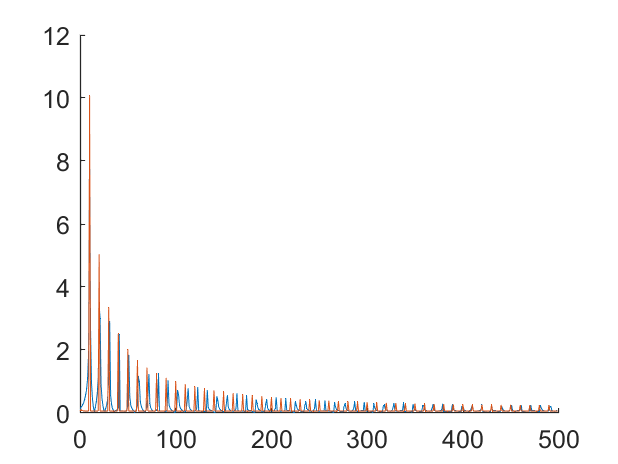

figure
hold on
plot(w(1:samples/2), (abs(X31(1:samples/2))))
plot(w(1:samples/2), (abs(X32(1:samples/2))))
hold off

## Other functions

This function returns angular frequency rather than normal frequency.

function w = fourierFreqs(t)
    sampling_rate = 1/(t(2) - t(1));
    N = length(t);
    w = 2*pi*sampling_rate*(0:N-1)/N;
end